**Laboratory - 8**

**MA 202 (Numerical techniques)**

**B. Tech. II year CSE**

**Name    - Valiveti Swamy Naga Sai Nivas**

**Roll No - 202051197**

**Question - 1**

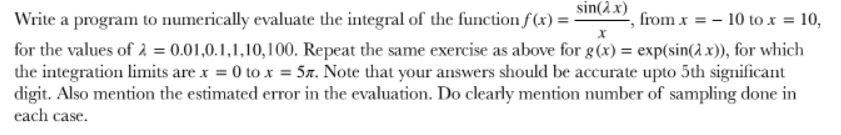

**Answer**

## **Function definitions are at the end of the file**

Error when lambda = 1.000000e-02 is 3.703591e-07
Error when lambda = 1.000000e-01 is 3.588446e-04
Error when lambda = 1 is 5.361984e-02
Error when lambda = 10 is 1.432070e-01
Error when lambda = 100 is 1.386428e+00


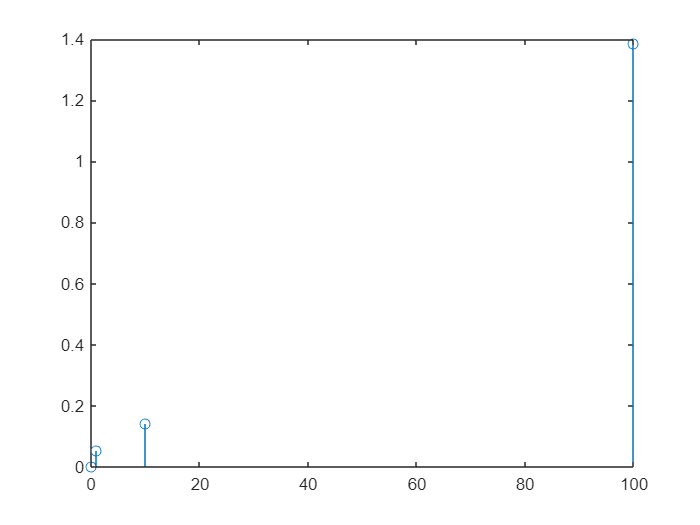

It can be seen clearly from the above calculations that with increase
in the value of lambda error also increases.

Here a very large sample of size 10000 is taken within the limits
to calculate the error



% Part - A
% For function sin(lambda*x)/x
lower_limit = -10;
upper_limit = 10;
generaterand = random(lower_limit,upper_limit,10000);
lambda = [0.01,0.1,1,10,100];
for i=1:5
    format default
    f = @(x) (sin(lambda(i)*x))/x;
    measured = (upper_limit - lower_limit) * montecarlo(generaterand,f,10000);
   
end

Error when lambda = 1.000000e-02 is 8.304897e-03
Error when lambda = 1.000000e-01 is 8.704100e-02
Error when lambda = 1 is 9.248795e-02
Error when lambda = 10 is 1.030584e-01
Error when lambda = 100 is 2.269153e-01


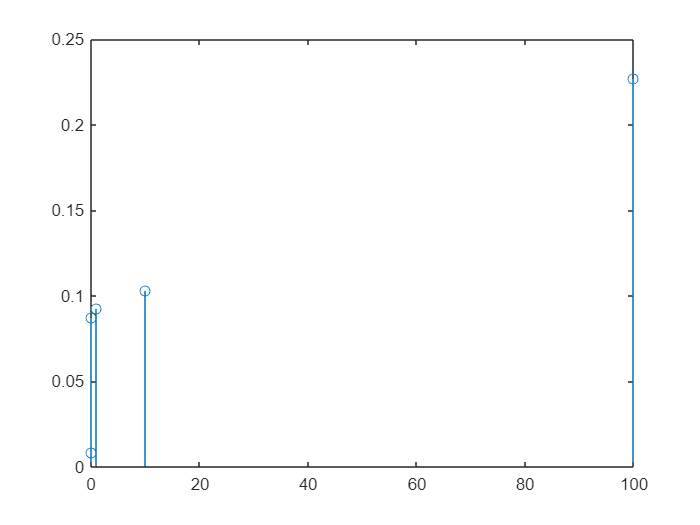

Here a very large sample of size 10000 is taken within the limits
to calculate the error


% Part - B
% For function e^(sin(lambda*x))
lower_limit = 0;
upper_limit = 5*pi;
generaterand = random(lower_limit,upper_limit,10000);
lambda = [0.01,0.1,1,10,100];
for i=1:5
    format default
    f = @(x) exp(sin(lambda(i)*x));
    measured = (upper_limit - lower_limit) * montecarlo(generaterand,f,10000);
end

**Question - 2**

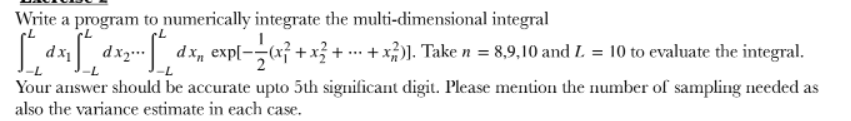

**Answer**

**Function definitions are at the end of the file**

clc;
clear all;
lower_limit = -10;
upper_limit = 10;
% For n = 8
for i = 1 : 8
    x(i,:) = random(lower_limit,upper_limit,10000000);
end
f = @(x1,x2,x3,x4,x5,x6,x7,x8) exp(-0.5*(x1.^2 + x2.^2 + x3.^2 + x4.^2 + x5.^2 + x6.^2 + x7.^2 + x8.^2));
answer1 = montecarlo8(x,f,10000000);
measured1 = (upper_limit - lower_limit).^8 * answer1;

If the value of n is 8 then integration value is 1.704494e+03 and variance is 2.033378e-09

In order to get the accurate result large number of randomdly
generated values need to be taken.


lower_limit = -10;
upper_limit = 10;
% For n = 9
for i = 1 : 9
    x(i,:) = random(lower_limit,upper_limit,10000000);
end
f = @(x1,x2,x3,x4,x5,x6,x7,x8,x9) exp(-0.5*(x1.^2 + x2.^2 + x3.^2 + x4.^2 + x5.^2 + x6.^2 + x7.^2 + x8.^2 ...
    + x9.^2));
answer2 =  montecarlo9(x,f,10000000);
measured2 = (upper_limit - lower_limit).^9 * answer2;

If the value of n is 9 then integration value is 1.205069e+03 and variance is 3.563503e-12

In order to get the accurate result large number of randomdly
generated values need to be taken.


lower_limit = -10;
upper_limit = 10;
% For n = 10
for i = 1 : 10
    x(i,:) = random(lower_limit,upper_limit,10000000);
end
f = @(x1,x2,x3,x4,x5,x6,x7,x8,x9,x10) exp(-0.5*(x1.^2 + x2.^2 + x3.^2 + x4.^2 + x5.^2 + x6.^2 + x7.^2 + x8.^2 ...
    + x9.^2 + x10.^2));
answer3 = montecarlo10(x,f,10000000);
measured3 = (upper_limit - lower_limit).^10 * answer3;

If the value of n is 10 then integration value is 1.742302e+03 and variance is 5.788989e-14

In order to get the accurate result large number of randomdly
generated values need to be taken.

It can be seen that with increase in the value of the n the variance decreases and integration
value increases.

**Question - 3**

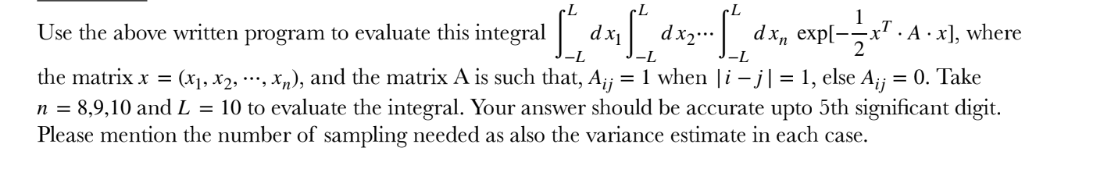

**Answer**

clc;
clear all;
lower_limit = -10;
upper_limit = 10;
% For n = 8

for i = 1:8
    for j = 1:8
        if abs(i-j) == 1
            A(i,j) = 1;
        else
            A(i,j) = 0;
        end
    end
end
sum  = 0;
for i = 1 : 10000
    x(:,i) = random(lower_limit,upper_limit,8);
    sum = sum + exp((-0.5*transpose(x(:,i))*A*x(:,i)));
end
sum = sum/10000;
sum = sum*(upper_limit - lower_limit).^8;

clc;
clear all;
lower_limit = -10;
upper_limit = 10;
% For n = 9

for i = 1:9
    for j = 1:9
        if abs(i-j) == 1
            A(i,j) = 1;
        else
            A(i,j) = 0;
        end
    end
end
sum  = 1;
for i = 1 : 10000
    x(:,i) = random(lower_limit,upper_limit,9);
    sum = sum + exp((-0.5*transpose(x(:,i))*A*x(:,i)));
end
sum = sum/10000;
sum = sum+(upper_limit - lower_limit).^9;
fprintf("The value of integration at n = 9 is %d",sum);

The value of integration at n = 9 is 2.228997e+171



clc;
clear all;
lower_limit = -10;
upper_limit = 10;
% For n = 10

for i = 1:10
    for j = 1:10
        if abs(i-j) == 1
            A(i,j) = 1;
        else
            A(i,j) = 0;
        end
    end
end
sum  = 0;
for i = 1 : 10000
    x(:,i) = random(lower_limit,upper_limit,10);
    sum = sum + exp((-0.5*transpose(x(:,i))*A*x(:,i)));
end
sum = sum/10000;
sum = sum*(upper_limit - lower_limit).^10;
fprintf("The value of integration at n = 10 is %d",sum);

The value of integration at n = 10 is 9.513936e+184


fprintf("Variance in this program will be very large as the integration value is too high");

Variance in this program will be very large as the integration value is too high

fprintf("\nWith increase in the value of n the error in the value of integration decreases");


With increase in the value of n the error in the value of integration decreases

function method = montecarlo(x,f,N)
    sum = 0;
    for i=1:N
        sum = sum + f(x(i));
    end
    method = (sum)/N;
end

% Declaring monte carlo method to calculate 8th order integral
function method = montecarlo8(x,f,N)
    sum = 0;
    for i=1:N
        sum = sum + f(x(1,i),x(2,i),x(3,i),x(4,i),x(5,i),x(6,i),x(7,i),x(8,i));
    end
    method = (sum)/N;
end

% Declaring monte carlo method to calculate 9th order integral
function method = montecarlo9(x,f,N)
    sum = 0;
    for i=1:N
        sum = sum + f(x(1,i),x(2,i),x(3,i),x(4,i),x(5,i),x(6,i),x(7,i),x(8,i),x(9,i));
    end
    method = (sum)/N;
end

% Declaring monte carlo method to calculate 10th order integral
function method = montecarlo10(x,f,N)
    sum = 0;
    for i=1:N
        sum = sum + f(x(1,i),x(2,i),x(3,i),x(4,i),x(5,i),x(6,i),x(7,i),x(8,i),x(9,i),x(10,i));
    end
    method = (sum)/N;
end

% Declaring function to generate random numbers
function generaterand = random(left,right,N)
    generaterand = left + (right - left).*rand(1,N);
end
